# Eksamen F2022

Mathias Bruun Houmøller  -  202006837

format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)
% latex(expr)

## Opgave 1

**a)**

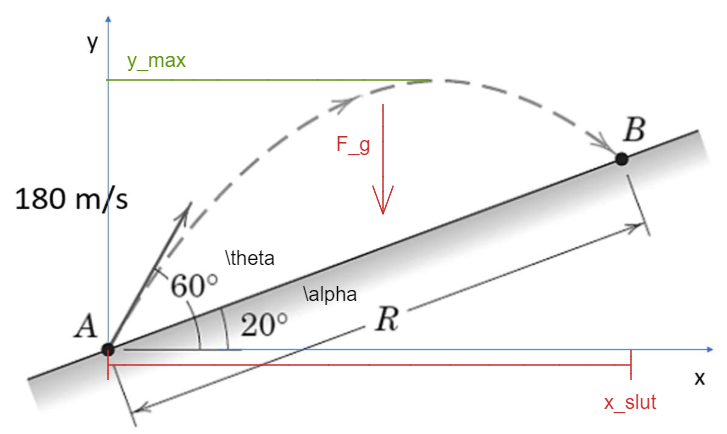

clear

syms t
g = -9.81; % m/s^2
a_0 = g; % der omnavngives
v_0 = 180; % m/s

theta = 60; % grader
alpha = 20; % grader

disp("For y komposanten har vi strækningen for max højden")

For y komposanten har vi strækningen for max højden


disp("når hastigheden v er 0.")

når hastigheden v er 0.


disp("Vi finder tiden t til denne position")

Vi finder tiden t til denne position



v_y0 = sind(theta) * v_0 % y komposanten af hastigheden

v_y0 =        155.88



v_y_eq = v_y0 + a_0 * t % hastighedsligningen opstilles

$$v\_y\_eq = 90\,\sqrt{3}-\frac{981\,t}{100}$$


t_cal = solve(0 == v_y_eq, t); %tiden findes.
t_ = vpa(t_cal, 4) 

$$t\_ = 15.89$$


disp("Vi indsætter nu tiden i sted funktionen")

Vi indsætter nu tiden i sted funktionen


disp("ved at integrere hastighedsfunktionen")

ved at integrere hastighedsfunktionen



y(t) = int(v_y_eq, t) % integrere hastihedsfunktione

$$y(t) = -\frac{9\,t\,\left(109\,t-2000\,\sqrt{3}\right)}{200}$$


fprintf("Max højden vi når er %f m", vpa(y(t_cal),4))

Max højden vi når er 1238.532110 m

**1,24 km er således den maximale højde vi kommer op på.**

**b)**

syms x

v_x0 = cosd(theta) * v_0 % y komposanten af hastigheden

v_x0 =     90




disp("Sted funktionen i x-retningen afhænger her kun af start hastigheden")

Sted funktionen i x-retningen afhænger her kun af start hastigheden


displayFormula("x = v_x0 * t")

$$x=90\,t$$



disp("Her kan t isolere og erstatte det i y-funktionen med x/v_x0")

Her kan t isolere og erstatte det i y-funktionen med x/v_x0


disp("Vi får ligningen")

Vi får ligningen



y(x) = v_y0 * x/v_x0 + a_0 * (x/v_x0)^2 / 2

$$y(x) = \sqrt{3}\,x-\frac{109\,x^{2}}{180000}$$

vpa(y(x),4)

$$ans = 1.732\,x-0.0006056\,x^{2}$$

**Vi har nu forskriften y(x) for projektilets banekurve som**


$$y\left(x\right)=\frac{v_{\mathrm{y0}}\,x}{v_{\mathrm{x0}}}+\frac{a_{0}\,x^2}{2\,{v_{\mathrm{x0}}}^2}$$


Vi plotter nu rampen sammen med bane kurven


y_rampe(x) = tand(alpha) * x; % ligning for rampen 
% (fordi vi har forholdet y/x = sin(x)* R/cos(x) * R = tan(x) = hældningen)
X_lin = linspace(0,2870,100); %linspace til plot

% plot af bane kurven
plot(X_lin, y(X_lin), "displayName", "Bane kurve")
hold on

% plot af rampe
plot(X_lin, y_rampe(X_lin), "displayName", "Rampe")

%formalia
% yline(double(y(t_cal)), 'g--', "displayName", "y-max")
yline(0, '--', "displayName", "0-linje")
grid()
legend('Location','NorthOutside')
ylabel('y-position(m)'), xlabel('x-position(m)')
hold off


**c)**



disp("afstanden R findes nu i skæringspunktet imellem rampen og banekurven")

afstanden R findes nu i skæringspunktet imellem rampen og banekurven


disp("Først findes x-afstanden")

Først findes x-afstanden


x_slut_eq = y(x) - y_rampe(x) %skæringpunktet for de to linjer

$$x\_slut\_eq = \sqrt{3}\,x-\frac{1639176211415221\,x}{4503599627370496}-\frac{109\,x^{2}}{180000}$$

x_slut_eq_ = vpa(x_slut_eq, 4)

$$x\_slut\_eq\_ = 1.368\,x-0.0006056\,x^{2}$$


x_slut = solve(x_slut_eq == 0, x); % vi finder x koordinatet i skæringspunktet

x_slut_ = vpa(x_slut(2), 5)

$$x\_slut\_ = 2259.2$$

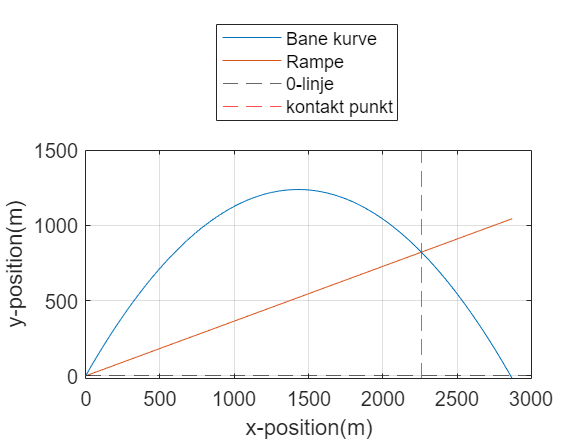


%plotter slut punkt linje
xline(double(x_slut_), 'r--', "displayName", "kontakt punkt")

disp("Vi kan nu finde rampens længde med x som")

Vi kan nu finde rampens længde med x som



% Finder R med trigomatri
R = x_slut(2) / cosd(alpha); % R = x/cos(alpha)
R_ = vpa(R,4)

$$R\_ = 2404.0$$

**Rampen R er således  2,40 km**

## Opgave 2

clear
disp('Vi opstiller vores data')

Vi opstiller vores data


theta = 0

theta =      0


omega = 4 %rad/s

omega =      4


m = 100 % kg

m =    100


k_G = 0.250 % m

k_G =          0.25


g = 9.81 %m/s^2

g =          9.81


d = 0.75 % m

d =          0.75


**a)**

disp("Vi bruge ligning B/2")

Vi bruge ligning B/2


I_G = k_G^2 * m

I_G =          6.25



$$I_G = 6,25\ kg\ m^2$$


**b)**

disp("Vi bruge ligning B/3 flytningsformlen")

Vi bruge ligning B/3 flytningsformlen


I_P = I_G + m * d^2

I_P =          62.5



$$I_C = 62,5\ kg \ m^2$$


**c)**

**FBD **i t-n koordinat system

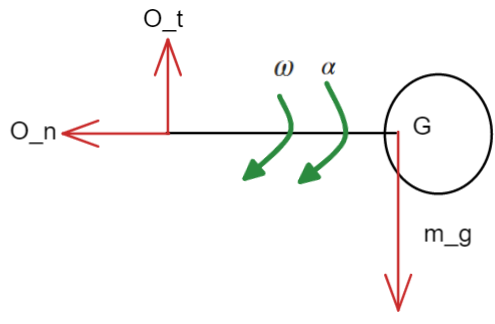

**d)**

**KD** i t-n koordinat system

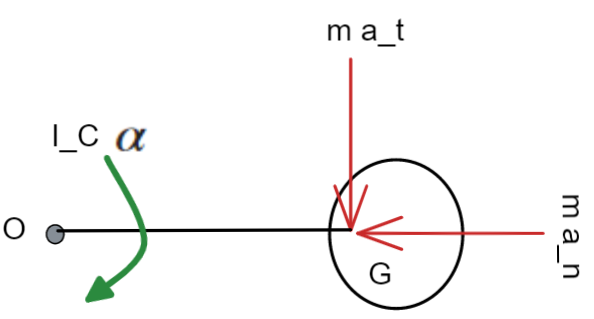

**e)**

**C = O**

Vi finder vinkelacceleration ved 0 grader via energi ligningen

da vi har $M_C = I_C \cdot \alpha$


$$V_g = m \cdot g \cdot h$$


h = d

h =          0.75


M_c = h * m * g; % =V_g
alpha = M_c / I_P

alpha =        11.772



$$\alpha =11,77 s^{-2}$$


**f)**

Vi finder reaktionskrafter ved 0 hvor vi ved at

for y-retningen


$$a_t = r \cdot \alpha$$


for x-retningen


$$a_n = r \cdot \omega^2$$


samt tyngde accelerations bidraget g

r = d % m

r =          0.75


C_x = -r * omega^2 * m %N

C_x =        -1200


%For y er der både bidrag fra rotation og fra tyngdekraften
C_y = -r * alpha * m + m * g %N

C_y =          98.1


Vi får således reaktionskrafterne


$$C_x = -1200\ N$$



$$C_y = 98,1\ N$$


**g)**

L_AC = 0.6 %m  = L_CB

L_AC =           0.6


L_AB = 2 * L_AC  %m

L_AB =           1.2


L_CC = 1 %m

L_CC =      1


%Sum x retning
% 0 = A_x + C_x
A_x = -C_x

A_x =         1200



%Sum moment i A
% 0 = B_y * L_AB - C_x * L_CC - C_y * L_AC 
% B_y * L_AB = C_x * L_CC + C_y * L_AC 

B_y = (C_x * L_CC + C_y * L_AC) / L_AB 

B_y =       -950.95



%Sum i y retning
% 0 = A_y + B_y - C_y

A_y = C_y - B_y

A_y =        1049.1


Således får vi reaktionskræfterne


$$A_x = -1200\ N$$



$$A_y = 1049\ N$$



$$B_y = -951\ N$$


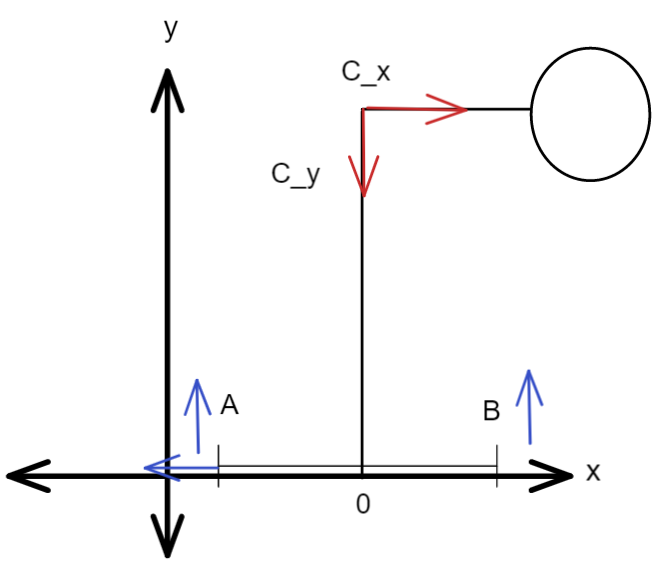

**c)**

## **Opgave 3**

**a)**

clear 

disp('Vi opstiller vores data')

Vi opstiller vores data


M = 1 % kg

M =      1


K1 = 10 % N/m

K1 =     10


K2 = 6 % N/m

K2 =      6


K3 = 10 % N/m

K3 =     10


g = 9.81 % m/s2

g =          9.81




disp('to fjeder i sidder i serie og disse er  i paralelle med en sidste fjeder')

to fjeder i sidder i serie og disse er  i paralelle med en sidste fjeder


k_venstre = 1/((1/K1) + (1/K2))

k_venstre =          3.75



k_tot = k_venstre + K3

k_tot =         13.75





disp('Egensvingningen findes')

Egensvingningen findes



w_n = sqrt(k_tot/M) %egensvingningen

w_n =        3.7081


n = w_n * 60 / (2*pi)

n =         35.41


Vi får således en egenfrekvens på


$$\omega_n = 3,7\ s^{-1}$$



$$n = 35,4\ omdr./min$$


**b)**

Da der ikke er nogen vinkel acceleration og dermed er den tangielle acceleration a_t = 0

Tyngde kraften fra kuglerne er med taget i beregningen for den samlede masse M

Således regnes kun på bidraget fra normal acceleration a_n

%data
disp('Data gevet')

Data gevet


m = 0.05 % kg

m =          0.05


e = 0.01 %m

e =          0.01


omega = 10 %rad/s

omega =     10



syms t

% Vi finder
disp('a_n findes sammen med F_n')

a_n findes sammen med F_n


a_n = e * omega^2

a_n =      1


F_n = a_n * m

F_n =          0.05


% F_g = 2*m*g

disp('Vi opskriver ligningen med bidrag fra begge elementer')

Vi opskriver ligningen med bidrag fra begge elementer


disp('Vi ganger på med pladseringen af massen hvor der er størst bidrag ved lodret position (sin)')

Vi ganger på med pladseringen af massen hvor der er størst bidrag ved lodret position (sin)



F_L(t) = 2 * F_n * sin(omega * t) % - F_g

$$F\_L(t) = \frac{\sin\left(10\,t\right)}{10}$$

displayFormula('F_L(t) =  2 * F_n * sin(omega * t)')

$$F_{L}\left(t\right)=\frac{2\,\sin\left(10\,t\right)}{20}$$


T = linspace(0,2);

disp('Vi plotter funktionen for bedre overblik')

Vi plotter funktionen for bedre overblik


plot(T, F_L(T)), grid(), yline(0, '--')
hold on


**c)**

Vi gør som ovenfor bare med $\omega_n$

a_n = e * w_n^2

a_n =        0.1375


F_n = a_n * m

F_n =      0.006875



F_L(t) = 2 * F_n * sin(w_n * t)% - F_g

$$F\_L(t) = \frac{11\,\sin\left(\frac{\sqrt{55}\,t}{2}\right)}{800}$$

displayFormula('F_L(t) =  2 * F_n * sin(w_n * t)')

$$F_{L}\left(t\right)=\frac{2\,11\,\sin\left(\frac{\sqrt{55}\,t}{2}\right)}{1600}$$



disp('Vi plotter funktionen for bedre overblik')

Vi plotter funktionen for bedre overblik


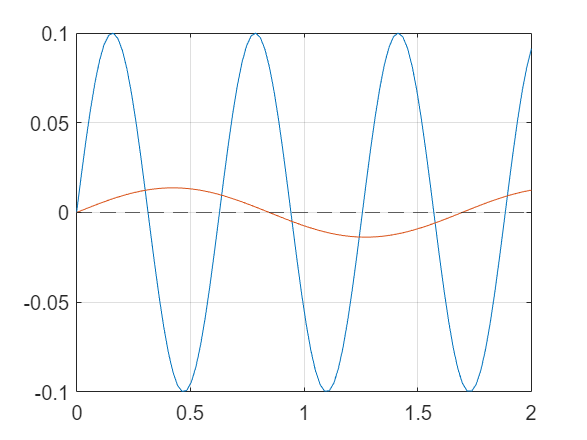

plot(T, F_L(T))
hold off

Denne ændinrg betyder en mindre variende kraftpåvirkning pr tid da frekvensen bliver lavere.

Kraften bliver 0,138 gange mindre, men fører til resonans i systemet, hvorved der opstår stor

risiko for at fjedrene deformeres kraftigt og konstruktionen ødelægges.